% Adjust the value of e here
e = 3.876706;

init = [0, 1]; % Initial conditions psi(u=0), psi'(u=0)
uMax = 3; % Maximum u to solve for
uReport = uMax; % Value of u to report psi at

% ODE SOLVER
opts = odeset('RelTol',1e-12,'AbsTol',1e-12); % Accuracy
[u,soln] = ode45(@ourderivatives, [0 uMax], init, opts, e); % Solve the ODE

% AMPLITUDE AND WAVELENGTH CALCULATION
psi=soln(:,1); % Grab the psi solution
psishift=[0; psi(1:length(psi)-1)]; % Shift the vector of values right by one entry
diff=psi-psishift; % Compute the difference between each value and the next
format('long'); % Report with lots of digits of precision
posL=find(diff < 0,1)-1; % Find the first time that the wavefunction decreases, and go back one step to find the maximum
AL=psi(posL) % Report the amplitude at the left

AL =    0.080833000157372


posR=find(diff > 0,1,'last'); % Find the last time that the wavefunction increases
AR=psi(posR) % Report the amplitude at the right

AR =    0.086946213284614


lambdaL=4*u(posL)

lambdaL =    0.507900318457132


lambdaR=4*(u(length(u)) - u(posR))

lambdaR =    0.589797349806513



% PROBLEM OUTPUT
result=interp1(u,soln(:,1), uReport);
texte=num2str(e,12);
disp(['For e = ',texte,', psi(',num2str(uReport),') = ',num2str(result)])

For e = 3.876706, psi(3) = 9.526e-07


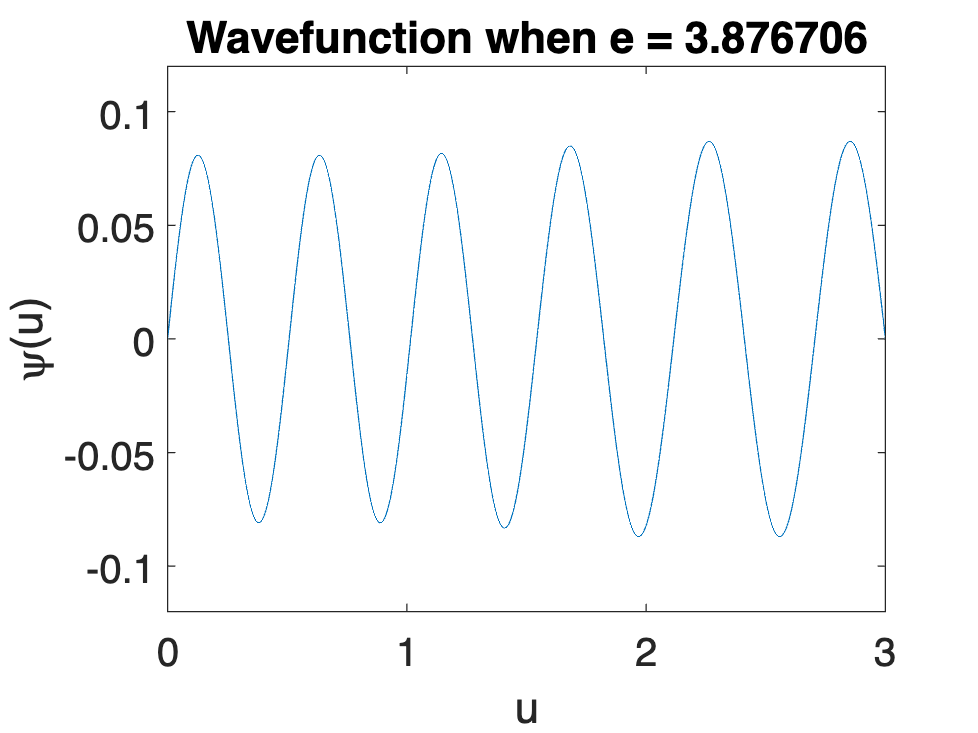

% Plot the solution
p=plot(u,soln(:,1));
p.Parent.FontSize = 16;
axis([0 uMax -0.12 0.12])
xlabel('u');
ylabel('\psi(u)');
title(['Wavefunction when e = ',texte]);


% POTENTIAL
% Call this function as f(u)
% f(u) = 0 for 0 <= u <= 1
% f(u) = u-1 for 1 < u <= 2
% f(u) = 1 for 2 < u <= 3

function potential = f(u)
    u1 = (u>=0 & u<=1);    % [0, 1]
    u2 = (u>1 & u<=2);    % (1, 2]
    u3 = (u>2 & u<=3);    % (2, 3]
    potential(u1) = 0;
    potential(u2) = u-1;
    potential(u3) = 1;
end

% ODE Definition - code your ODE here!!!
function derivatives = ourderivatives(u,psi,e)
    % psi(1) = psi(u), psi(2) = psi'(u)
    % derivatives = [psi'(u); psi''(u)];
    derivatives = [psi(2); 4*pi^2*psi(1)*(f(u)-e)];
end
